
%#ok<*CLALL>

clear all;clc 

% Sim settings. 
maxSpeed = 1E-1; 
timeStep = 4; 

% Initial states. 
initialStates = [-1; 0; 1; 0; maxSpeed; 0; 0; maxSpeed]; 

% Position constraints. 
areaBounds = [-1; 1; -1; 1]*50; 

% TPBVP test time span input. 
tspan = 0 : 1E-2 : timeStep; 

% Initial guess. 
% guess = [ ...
%     initialStates; ...
%     (initialStates(1)-initialStates(3)); ...
%     (initialStates(2)-initialStates(4)); ...
%     -(initialStates(1)-initialStates(3)); ...
%     -(initialStates(2)-initialStates(4)); ...
%     zeros(4, 1)]; 
guess = 1E-1*ones(16, 1); 
guess(1:8) = [ ...
    initialStates(3); ...
    initialStates(4); ...
    initialStates(3)+timeStep*initialStates(7); 
    initialStates(4)+timeStep*initialStates(8); ...
    initialStates(7); ...
    initialStates(8); ...
    initialStates(7); ...
    initialStates(8)]; 
guess(9) = (guess(1)-guess(3)); 
guess(10) = (guess(2)-guess(4)); 
guess(11) = -(guess(1)-guess(3)); 
guess(12) = -(guess(2)-guess(4)); 
disp(guess); 

    1.0000
         0
    1.0000
    0.4000
         0
    0.1000
         0
    0.1000
         0
   -0.4000
         0
    0.4000
    0.1000
    0.1000
    0.1000
    0.1000



solGuess = bvpinit(tspan, guess); 
options = bvpset("Stats", "on"); 
sol = bvp4c( ...
    @(t, y) eqns(t, y, maxSpeed, areaBounds), ...
    @(y_a, y_b) boundaryConditions(y_a, y_b, initialStates), ...
    solGuess, options); 

The solution was obtained on a mesh of 1042 points.
The maximum residual is  8.966e+00. 
There were 28939 calls to the ODE function. 
There were 147 calls to the BC function. 


solGuess = bvpinit(tspan, sol.y(:, end)); 
sol = bvp4c( ...
    @(t, y) eqns(t, y, maxSpeed, areaBounds), ...
    @(y_a, y_b) boundaryConditions(y_a, y_b, initialStates), ...
    solGuess, options); 

The solution was obtained on a mesh of 785 points.
The maximum residual is  4.856e+00. 
There were 26552 calls to the ODE function. 
There were 144 calls to the BC function. 


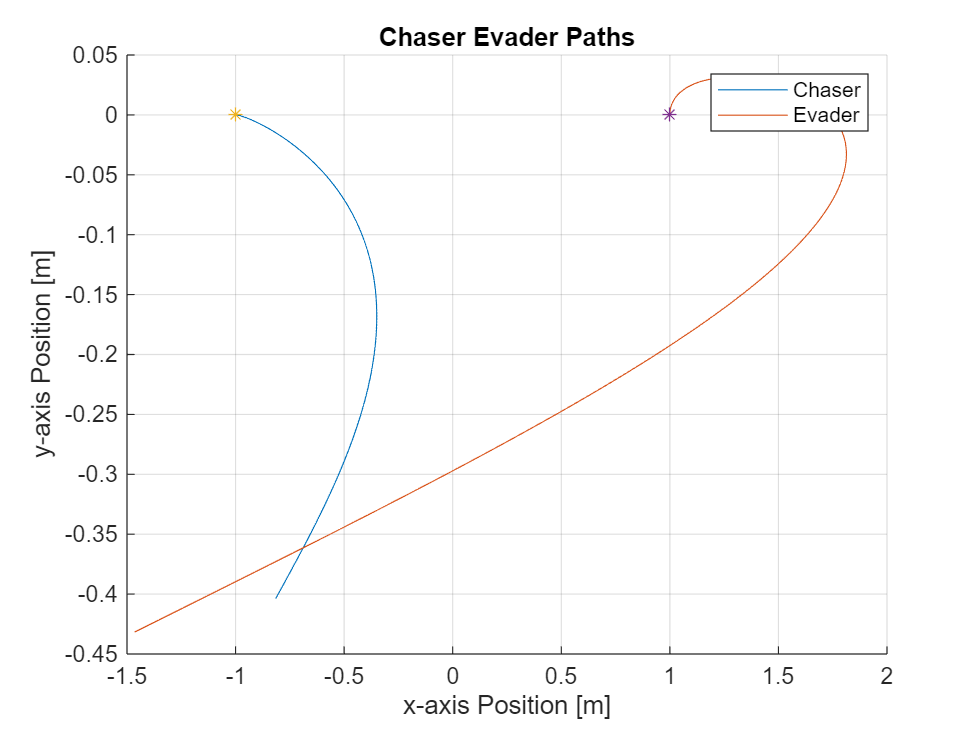

tspan = sol.x; 
y = sol.y; 
chaserPath = y(1:2, :); 
evaderPath = y(3:4, :); 

clf; 
hold on; 
grid on; 
plot(chaserPath(1, :), chaserPath(2, :), evaderPath(1, :), evaderPath(2, :)); 
plot(chaserPath(1, 1), chaserPath(2, 1), "*"); 
plot(evaderPath(1, 1), evaderPath(2, 1), "*"); 
title("Chaser Evader Paths"); 
xlabel("x-axis Position [m]"); 
ylabel("y-axis Position [m]"); 
legend("Chaser", "Evader"); 
% axis([-2 1 -1 1.6]); 
hold off;  

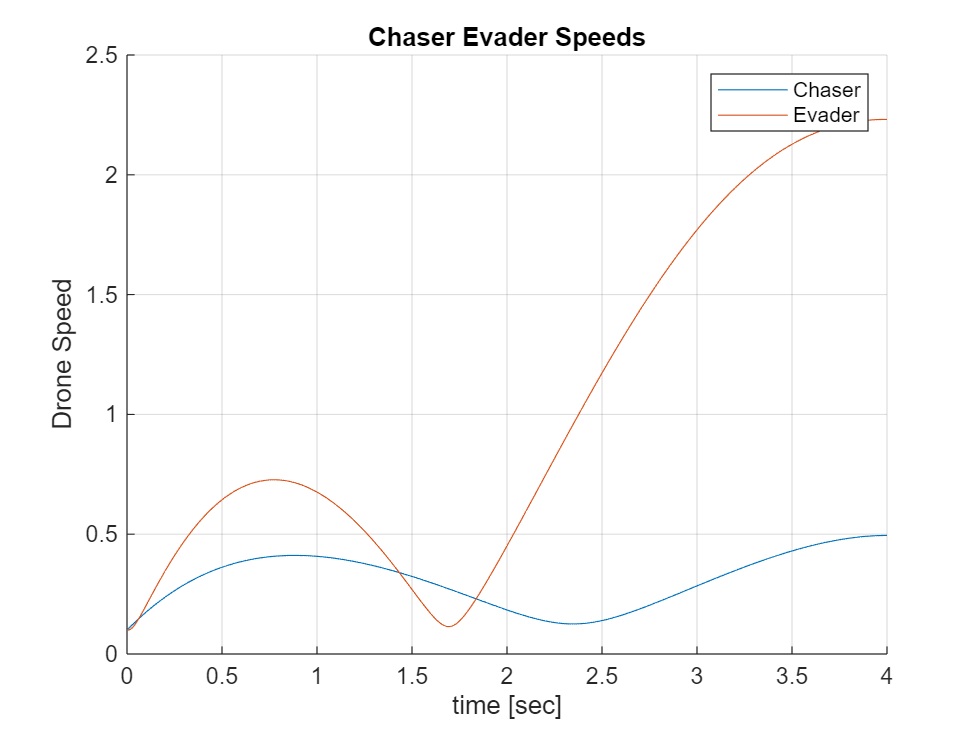

clf; 
hold on; 
grid on; 
plot(tspan, sqrt(y(5, :).^2+y(6, :).^2)); 
plot(tspan, sqrt(y(7, :).^2+y(8, :).^2)); 
title("Chaser Evader Speeds"); 
xlabel("time [sec]"); 
ylabel("Drone Speed"); 
legend("Chaser", "Evader"); 
hold off; 

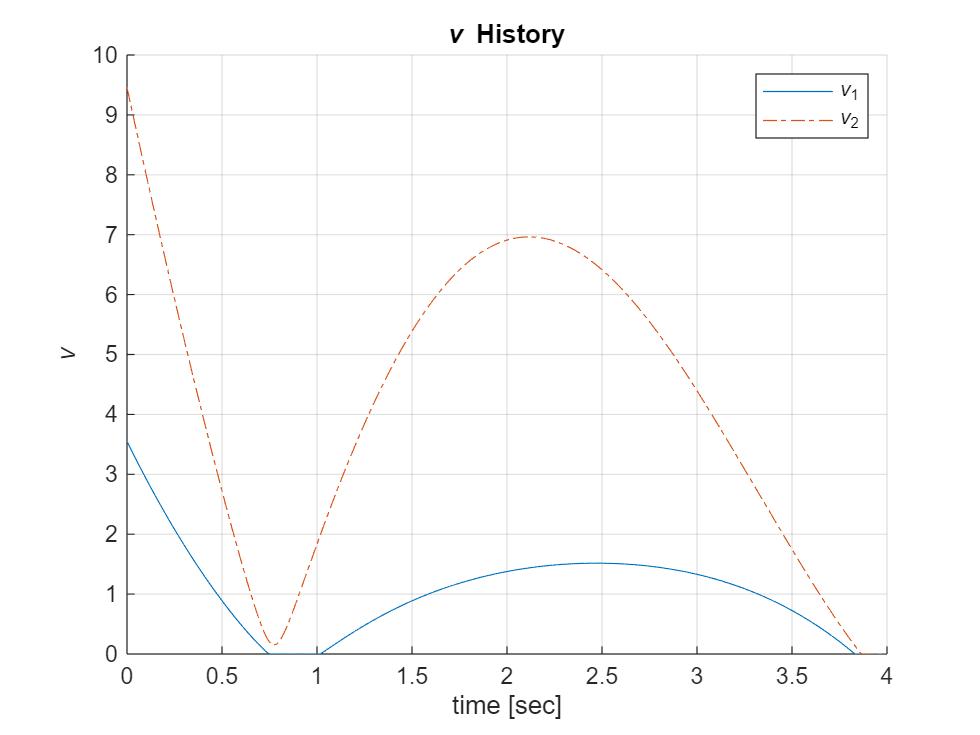

nu_history = max([ ...
        0.5*(sqrt(y(13, :).^2+y(14, :).^2)/maxSpeed-1); ...
        0.5*(sqrt(y(15, :).^2+y(16, :).^2)/maxSpeed-1)], 0); 
clf; 
hold on; 
grid on; 
plot(tspan, nu_history(1, :)); 
plot(tspan, nu_history(2, :), "-."); 
title("\nu History"); 
xlabel("time [sec]"); 
ylabel("\nu"); 
legend("\nu_1", "\nu_2"); 
hold off; 

% Differential equations. 
function dydt = eqns(~, y, maxSpeed, areaBnds)
    % Optimal Control. 
    u = [ ...
        -y(13:14); y(15:16)]; 

    % Position and velocity constraints. 
    mu = max([ ...
        areaBnds(1)-y(1); ...
        y(1)-areaBnds(2); ...
        areaBnds(3)-y(2); ...
        y(2)-areaBnds(4); ...
        areaBnds(1)-y(3); ...
        y(3)-areaBnds(2); ...
        areaBnds(3)-y(4); ...
        y(4)-areaBnds(4)], 0); 
    nu = max([ ...
        -maxSpeed-y(1); ...
        y(1)-maxSpeed; ...
        -maxSpeed-y(2); ...
        y(2)-maxSpeed; ...
        -maxSpeed-y(3); ...
        y(3)-maxSpeed; ...
        -maxSpeed-y(4); ...
        y(4)-maxSpeed], 0); 

    A = [zeros(4) eye(4); zeros(4) zeros(4)]; 
    B = [zeros(4); eye(4)]; 

    dydt = [ ...
        A*y(1:8)+B*u; ...
        nu(1)-nu(2); ...
        nu(3)-nu(4); ...
        nu(5)-nu(6); ...
        nu(7)-nu(8); ...
        mu(1)-mu(2)-y(9); ...
        mu(3)-mu(4)-y(10); ...
        mu(5)-mu(6)-y(11); ...
        mu(7)-mu(8)-y(12)]; 
end

% Boundary conditions. 
function retval = boundaryConditions(y_a, y_b, initialStates)
    retval = [ ...
        y_a(1:8)-initialStates; ...
        y_b(9:16) - [ ...
        y_b(1)-y_b(3); ...
        y_b(2)-y_b(4); ...
        -(y_b(1)-y_b(3)); ...
        -(y_b(2)-y_b(4)); ...
        zeros(4, 1)]]; 
end

% % fmincon nonlinear constraints. 
% function [c, ceq] = nonlcon(u, maxSpeed)
%     c = [u(1)^2+u(2)^2; u(3)^2+u(4)^2]-maxSpeed^2; 
%     ceq = []; 
% end